# Factorización *PCA y NMF*

## Importación y limpiado de la imagen + detección de *blobs*

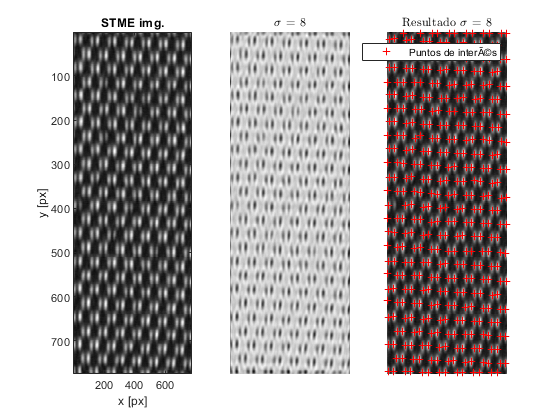

clc, clear, close all

% Leemos el mapa de bits que sale del microscopio
I = imread('../data/ADF.png');
I = double(rgb2gray(I));

% Normalizamos
I = I/max(max(I));

% Limpiamos el ruido de la imagen con FFT
thresh = 0.001;
Yt = fft2(I);
Max = max(max(abs(Yt)));
ind = abs(Yt) > thresh*Max;
Atlow = single(Yt .* ind);
Ilow = double(ifft2(Atlow));

% Detección de blobs por NLoG (pesado de compilar)
sgm_list = 8;
[x,y] = blobDetector(Ilow,sgm_list,0.028,1);

## Extracción de los parches de información

Generamos la Figura 8 para visualizar cómo se va a construir la matriz $X$:

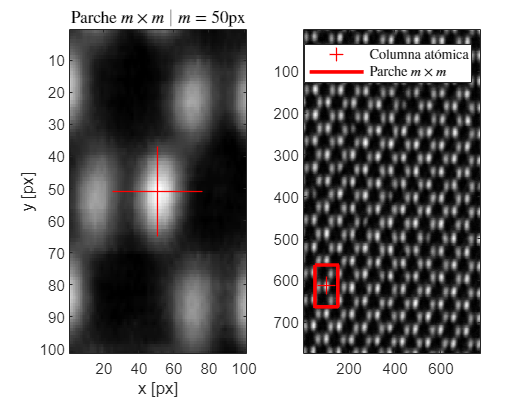

m = 50; % Distacia respecto al blob a cada lado
i = 49; % Elegimos una columna que cumpla las condiciones

figure(1), clf;

% Extraemos el parche seleccionado
I_patch = I(y(i)-m : y(i)+m ,x(i)-m : x(i)+m);
                                               
subplot(1,2,1)
imagesc(I_patch), colormap gray, hold on;
plot(m+1,m+1,'r+', 'MarkerSize', 50, 'LineWidth', 0.7)
title("Parche $m\times m$ $|$ $m = $" + num2str(m) + "px",'interpreter','latex')
xlabel("x [px]"), ylabel("y [px]")

% Dibujamos localización del parche en la imagen
x1 = x(i)-m; y1 = y(i)-m;
x2 = x(i)-m; y2 = y(i)+m;
x3 = x(i)+m; y3 = y(i)+m;
x4 = x(i)+m; y4 = y(i)-m;

subplot(1,2,2)
imagesc(I), colormap gray, hold on;
plot(x(i),y(i),'r+', 'MarkerSize', 10, 'LineWidth', 0.7)
plot([x1 x2 x3 x4 x1],[y1 y2 y3 y4 y1], "-r", "LineWidth",2)
legend("Columna at\'omica", "Parche $m\times m$",'interpreter', 'latex')

Una vez mostrado el proceso, generamos el tensor de información $T$ para posteriormente aplanarlo y transformarlo en la matriz $X$ que procesaremos por los distintos métodos de factorización matricial:

m = 50; % Distacia respecto al blob a cada lado

% Contabilizamos cuántos parches vamos a generar para inicializar T y X
patchs = 0;
for i = 1:length(x)
    if (x(i) > m && y(i) > m) && (x(i) < (size(I,2) - m) && y(i) < (size(I,1) - m))
        patchs = patchs + 1;
    end
end
T = zeros(2*m+1 ,2*m+1, patchs);
X = zeros(patchs, (2*m+1)^2);

% Extraemos todos los parches
patch = 1;
for i = 1:length(x)
    if (x(i) > m && y(i) > m) && (x(i) < size(I,2) - m && y(i) < size(I,1) - m)
        I_patch = I(y(i)-m : y(i)+m ,x(i)-m : x(i)+m);
        T(:,:,patch) = I_patch;
        patch = patch + 1;
    end
end

% Depuración para comprobar que T es correcto
%figure(2), clf;
%imagesc(T(:,:,length(T)))

% Aplanamos el tensor
X = reshape(T, (2*m+1)^2, patchs)';

% Depuración para comprobar que X es correcto (igual a figure(2)?)
%figure(3), clf;
%imagesc(reshape(X(:,length(T)),2*m+1,2*m+1))

% Separamos los datos entre train_data y test_data
n1 = 268;
n2 = 100;

X_train = X;
X_train(n1,:) = [];
X_train(n2,:) = [];

X_test = [X(n1,:) ; X(n2,:)];

## Descomposición PCA $(X = UV')$

% Hacemos uso del algoritmo implementado en MATLAB
% (requiere "Statistics and Machine Learning Toolbox")
[V,U,s2] = pca(X_train);

% Nos quedamos con los dos primeros coeficientes porque son los que tienen
% una mayor varianza (s2)
disp("Varianza de 4 primeras PC")

Varianza de 4 primeras PC


disp(s2(1:4))

  184.5105
    3.0395
    2.2505
    1.9147




% Visualizamos las dos componentes principales escogidas
U = U/max(max(abs(U)));

figure(4), clf;
subplot(3,4,[1 5 9]);
plot(U(:,1),U(:,2),".b"), grid on, hold on;
xlim([-1.1 1.1]), ylim([-1.1 1.1])
xlabel("Primera componente principal")
ylabel("Segunda componente principal")
title("PCA: Primeras dos componentes")

%biplot(V(:,1:2),'scores',score(:,1:2)), hold on;

% Dibujamos círculos para distinguir los distintos grupos
% (requiere Symbolic Math Toolbox)
plotcircle(0.17,-0.8,0.0,"k");
text(-0.6,0.00,'\leftarrowSe')

plotellipse(0.5,0.2,pi/2,0.78,0,"k");
text(0.1,0,'Mo\rightarrow')

% Mostramos la imagen reconstruida a partir de las
% primeras componentes principales
X_ = U(:,1:2)*V(:,1:2)';
X_ = X_/max(max(abs(X_)));
I_ = reshape(X_(266,:),2*m+1,2*m+1);
subplot(3,4,2);
imagesc(I_), colormap default; colorbar
text(145,0,'Se'), text(145,90,'Mo')
title("\textbf{PCA }$| \; X = U \times V$","Interpreter","latex")

% Mostramos las componentes por separado
X_2 = U(:,1)*V(:,1)';
X_2 = X_2/max(max(abs(X_2)));
I_1 = reshape(X_2(266,:),2*m+1,2*m+1);
subplot(3,4,6);
imagesc(I_1), colormap default; colorbar
title("p = 1","Interpreter","latex")

X_2 = U(:,2)*V(:,2)';
X_2 = X_2/max(max(abs(X_2)));
I_2 = reshape(X_2(266,:),2*m+1,2*m+1);
subplot(3,4,10);
imagesc(I_2), colormap default; colorbar
title("p = 2","Interpreter","latex")
xlabel("x [px]"), ylabel("y [px]")

% % Distinguimos entre las dos especies
% delta = 0.5;
% 
% mask = I_ > delta;
% I_Se = I_ .* mask;
% subplot(3,4,8);
% imagesc(I_Se), colormap default; colorbar;
% title("Se filtrado")
% caxis([-0.7 0.5])
% 
% mask = I_ < -delta;
% I_Mo = I_ .* mask;
% subplot(3,4,12);
% imagesc(I_Mo), colormap default; colorbar;
% title("Mo filtrado")
% caxis([-0.7 0.5])

Almacenamos estos resultados para que sean aprovechados por la red neuronal:

% Almacenamos X_test + U y V de las dos primeras componentes principales
writematrix(X_train  ,"../capitulo_3/fact_output/X_train.csv");
writematrix(X_test  ,"../capitulo_3/fact_output/X.csv");
writematrix(U(:,1:2),"../capitulo_3/fact_output/U.csv");
writematrix(V(:,1:2),"../capitulo_3/fact_output/V.csv");

## Descomposición NMF

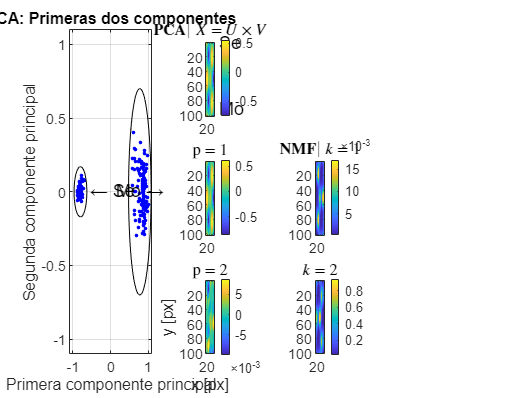

% Realizamos la factorización NMF
[Un,Vn] = nnmf(X,2);

% Mostramos las dos componentes
X_1 = Un(:,1)*Vn(1,:);
X_1 = X_1/max(max(abs(X_1)));
I_1 = reshape(X_1(268,:),2*m+1,2*m+1);
subplot(3,4,7);
imagesc(I_1), colorbar
title("\textbf{NMF }$| \; k = 1$","Interpreter","latex")

X_2 = Un(:,2)*Vn(2,:);
X_2 = X_2/max(max(abs(X_2)));
I_2 = reshape(X_2(268,:),2*m+1,2*m+1);
subplot(3,4,11);
imagesc(I_2), colorbar
title("$k = 2$","Interpreter","latex")

## Generación de vectores descriptores PCA

Teniendo en cuenta que en la descomposición PCA $X = UV'$, podremos generar los vectores descriptores para cada observación tomando $XV = U$. Cada  fila de la matriz resultante corresponderá al descriptor de la columna atómica en cuestión.

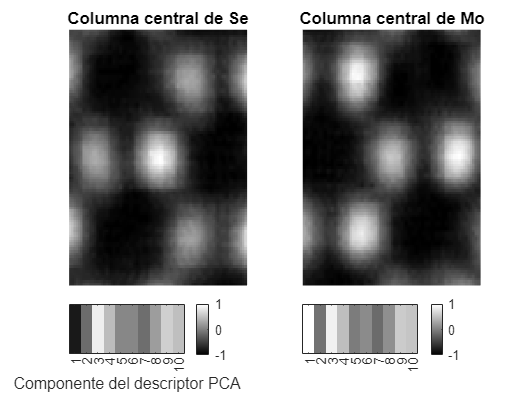

% Tomamos 2 columnas atómicas como ejemplo
% (corresponderan con los dos casos posibles)

% Representamos sus correspondientes parches
figure(2), clf;

n1 = 268;
subplot(5,2,[1 3 5 7])
imagesc(reshape(X(n1,:),2*m+1,2*m+1)), colormap gray, axis off
title("Columna central de Se")

n2 = 100;
subplot(5,2,[2 4 6 8])
imagesc(reshape(X(n2,:),2*m+1,2*m+1)), colormap gray, axis off
title("Columna central de Mo")

% Generamos los vectores descriptores
k = 10;

desc = [X(n1,:) ; X(n2,:)] * V(:,1:k);
desc = desc./max(max(abs(desc)));

subplot(5,2,9)
imagesc(desc(1,:)), colorbar
caxis([-1 1])
set(gca,'xtick',1:k)
set(gca,'ytick',[])
xlabel("Componente del descriptor PCA")

subplot(5,2,10)
imagesc(desc(2,:)), colorbar
caxis([-1 1])
set(gca,'xtick',1:k)
set(gca,'ytick',[])